# SSE Surfaces and the Hessian

Note: this script reproduces the figure of SSE functions for different Hessian matrices in Section 5.2 of **Statistics for Chemical Engineers**. Victor Z UW-Madison, 2019 examples of quadratic surfaces

clc; clear all; close all hidden; format short; 

## Sharp minimum

generate a surface with sharp minimum

H=[2 0; 0 2]

H =      2     0
     0     2


eigs(H)

ans =      2
     2


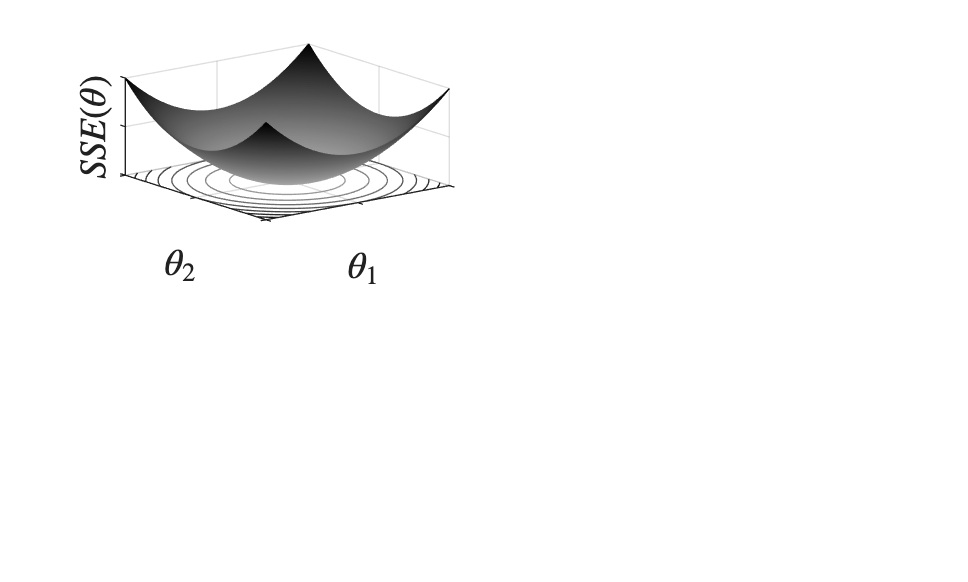


figure(1)
subplot(2,2,1)
c=linspace(0.7,0.0,64)';
C=[c,c,c];
[X1,X2] = meshgrid(-1:0.005:1);
SSE = H(1,1)*X1.^2 + 2*H(1,2)*X1.*X2 +H(2,2)*X2.^2;
meshc(X1,X2,SSE)
colormap(C);
grid on
set(gca,'Xticklabel',[])
set(gca,'Yticklabel',[])
set(gca,'Zticklabel',[])
xlabel('$\theta_1$','Interpreter','latex','FontSize',14)
ylabel('$\theta_2$','Interpreter','latex','FontSize',14)
zlabel('$SSE(\theta)$','Interpreter','latex','FontSize',14)

## Flat minimum

generate a surface with flat minimum

H=[2 2; 2 2]

H =      2     2
     2     2


eigs(H)

ans =      4
     0


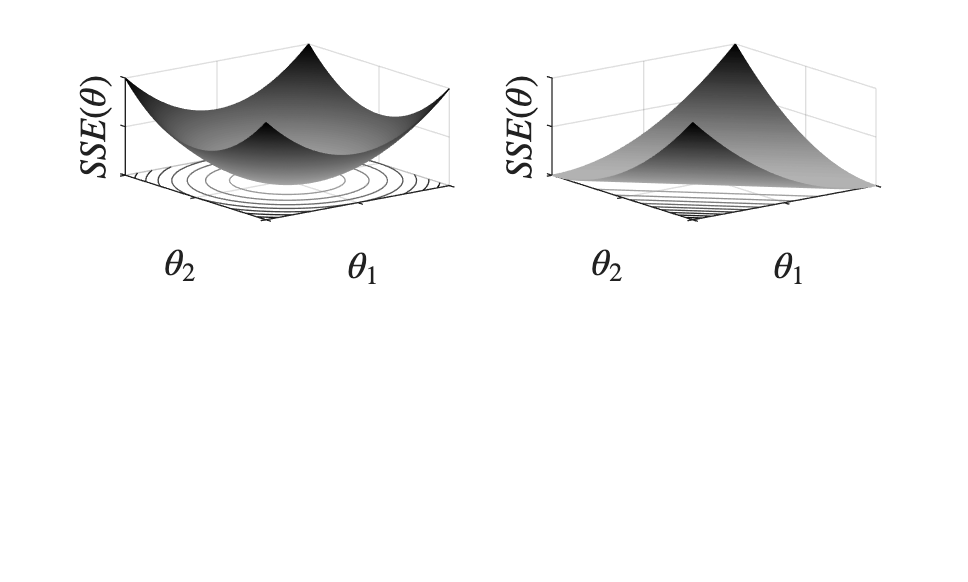


figure(1)
subplot(2,2,2)
C=[c,c,c];
[X1,X2] = meshgrid(-0.5:0.005:0.5);
SSE = H(1,1)*X1.^2 + 2*H(1,2)*X1.*X2 +H(2,2)*X2.^2;
meshc(X1,X2,SSE)
colormap(C);
grid on
set(gca,'Xticklabel',[])
set(gca,'Yticklabel',[])
set(gca,'Zticklabel',[])
xlabel('$\theta_1$','Interpreter','latex','FontSize',14)
ylabel('$\theta_2$','Interpreter','latex','FontSize',14)
zlabel('$SSE(\theta)$','Interpreter','latex','FontSize',14)

## Maximum

generate a surface with a maximum

H = -[2 0; 0 2]

H =     -2     0
     0    -2


eigs(H)

ans =     -2
    -2


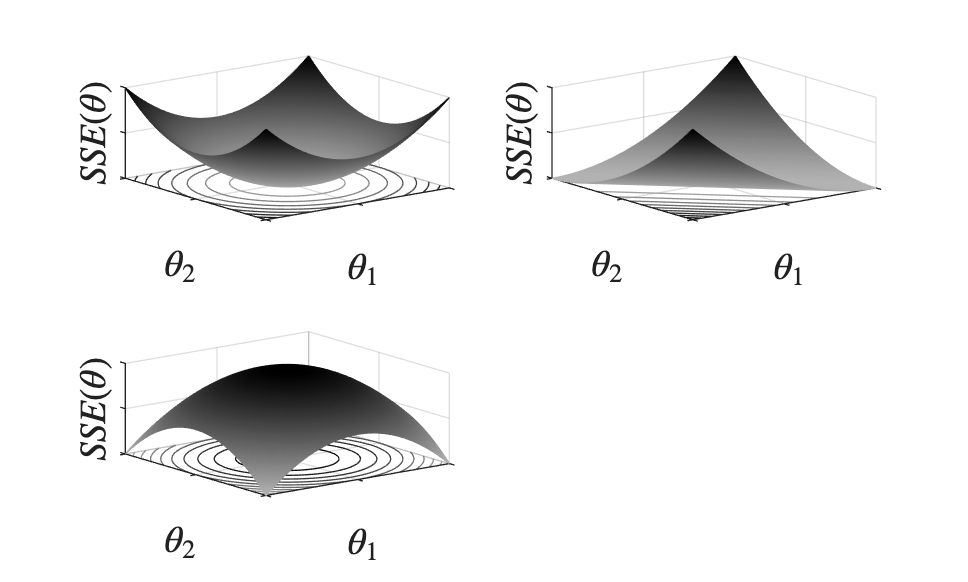


figure(1)
subplot(2,2,3)
C=[c,c,c];
[X1,X2] = meshgrid(-0.5:0.005:0.5);
SSE = H(1,1)*X1.^2 + 2*H(1,2)*X1.*X2 +H(2,2)*X2.^2;
meshc(X1,X2,SSE)
colormap(C);
set(gca,'Xticklabel',[])
set(gca,'Yticklabel',[])
set(gca,'Zticklabel',[])
xlabel('$\theta_1$','Interpreter','latex','FontSize',14)
ylabel('$\theta_2$','Interpreter','latex','FontSize',14)
zlabel('$SSE(\theta)$','Interpreter','latex','FontSize',14)

## Saddle point

generate a surface with saddle point

H=[1 2; 2 1]

H =      1     2
     2     1


eigs(H)

ans =      3
    -1


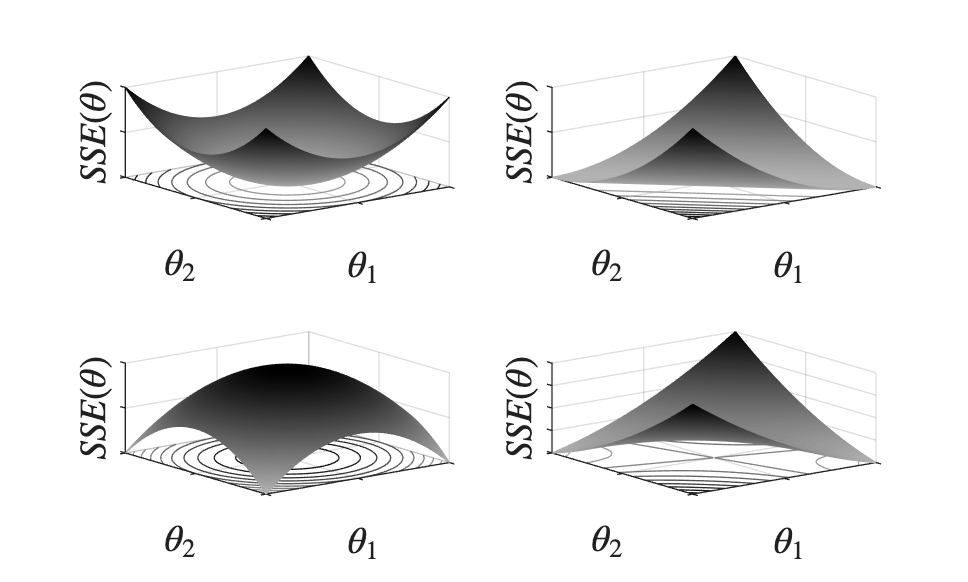


figure(1)
subplot(2,2,4)
C=[c,c,c];
[X1,X2] = meshgrid(-0.5:0.005:0.5);
SSE = H(1,1)*X1.^2 + 2*H(1,2)*X1.*X2 +H(2,2)*X2.^2;
meshc(X1,X2,SSE)
colormap(C);
set(gca,'Xticklabel',[])
set(gca,'Yticklabel',[])
set(gca,'Zticklabel',[])
xlabel('$\theta_1$','Interpreter','latex','FontSize',14)
ylabel('$\theta_2$','Interpreter','latex','FontSize',14)
zlabel('$SSE(\theta)$','Interpreter','latex','FontSize',14)


print -depsc -r1200 ch5_surfaces_quadratic.eps 

## Note

A Hessian with positive eigenvalues defines a unique (sharp) minimum; zero eigenvalues give a flat valley, where the estimate is not unique.